# 1)

a) graythresh bekommt als Input ein Grauwertbild und berechnet mit diesem (Otsu-Methode) den Schwellenwert. Dieser kann für die methode imbinarize verwendet werden. Diese Methode bekommt ein Grauwertbild und einen Schwellen wert und wandelt dieses in ein Binärbild um. otsuthresh erechnet ebenfalls einen Schwellenwert der mit imbinarize verwendet werden kann. Zusätzlich kann otsuthresh die 'effektvität' des threshholds zurückgeben. adaptthresh berechnet einen Schwellenwert für jede Region des Inputbildes. b) Das Segmentieren ist schwierig da es in dem Bild zu viel Rauschen gibt und das die berechnung eines Schwellenwerts auf basis eines Histograms schwierig macht.

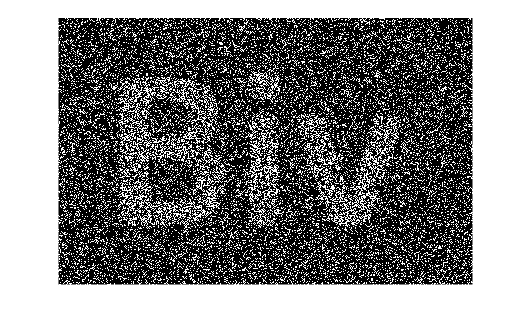

image = imread("BIVr.png");
threshhold = graythresh(image);
binary = imbinarize(image, threshhold);
figure;
imshow(binary);

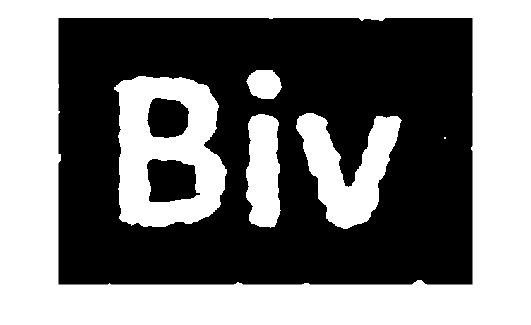

% c)
glatt = imgaussfilt(image, 5);
threshglatt = graythresh(glatt);
glattbin = imbinarize(glatt, threshglatt);
figure;
imshow(glattbin);

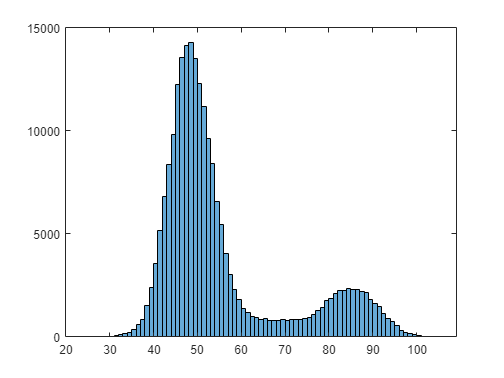

figure;
histogram(glatt);

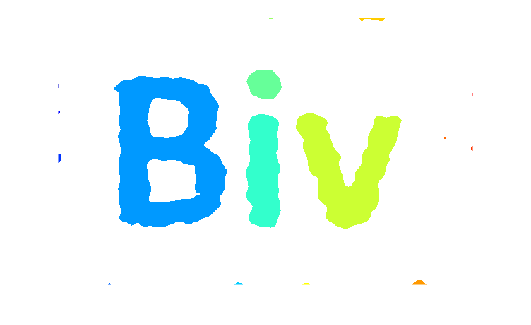

% Der mittelwert liegt etwas links der Mitte auf dem weg vom westen goßen
% peak nach unten in ein tal.

% d)
label_img = bwlabel(glattbin);
rgb = label2rgb(label_img);
figure;
imshow(rgb);


% e)
label_stats = regionprops(label_img, 'Area');
areas = [label_stats.Area];
areas = sort(areas);
% Die Anzahl der Pixel auf dem I-Punkt beträgt 1595
% Das areas array is aufsteigend sortiert und der I-Punkt ist die 4-Größte
% region im Bild.
areas(length(areas) - 3)

ans = 1595


% f)
length(areas)

ans = 17

## 2)

a)

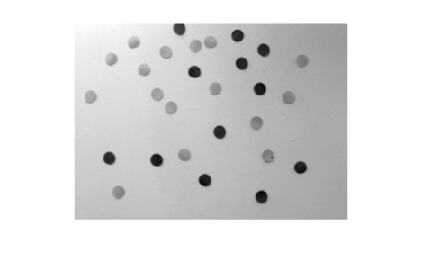

img = imread("shading.jpg");
shading = im2gray(im2double(img));
figure;
imshow(shading, []);

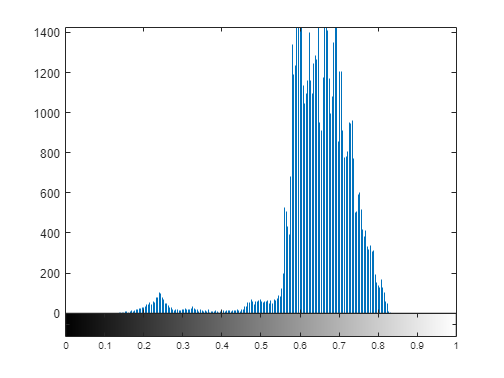

figure;
imhist(shading);

threshhold = graythresh(shading);
threshhold

threshhold = 0.4745

[levels, metric] = multithresh(shading, 2);
levels

levels =     0.4353    0.6558


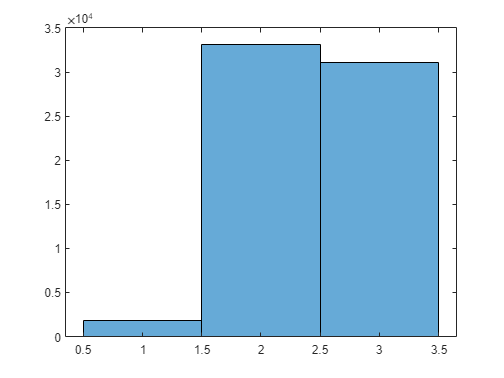

shading_quant = imquantize(shading, levels);
figure;
histogram(shading_quant);

% Das ergebnis enthält 3 verschiedene grauwerte.
length(unique(shading_quant))

ans = 3

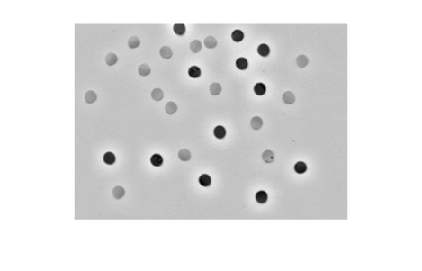


% b) 
% Der kleinste balken im histogram müssten die dunklen kugeln sein,
% die anderen beiden Balken sind hintergrund und die helleren kugeln diese
% sind allerdings gemischt.

% c)
glatt_sh = imgaussfilt(shading, 10);
glatt_sh = double(glatt_sh) / 255;
% d)
korektur = double(shading) ./ glatt_sh;
korektur = korektur / max(korektur(:));
figure;
imshow(korektur, []);

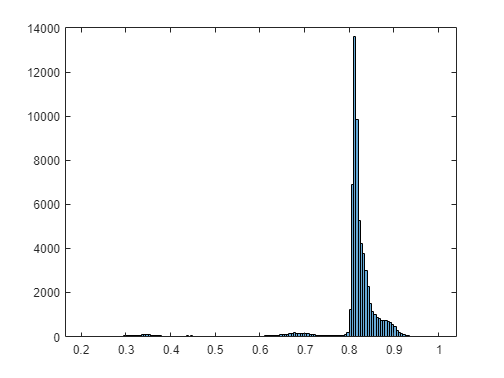


% e)
% Im Originalbild gibt es deutlich mehr ausschläge da es viele verschiedene
% Grauwerte gibt im Korrekturbild ist der Große peak der background Der
% sehr kleine hügel be ~0.35 die schwarzen kugeln und der etwas größere
% hügel bei ~0.66 die Grauen kugeln.
figure;
histogram(korektur);

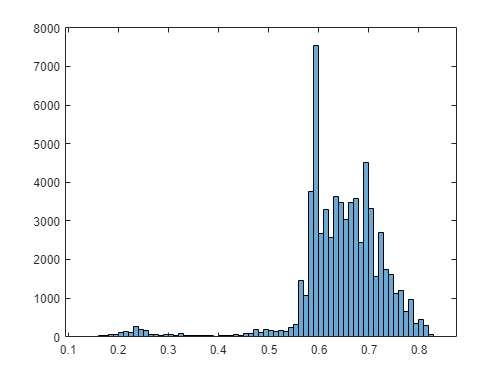

histogram(shading);


% f)
thresh = graythresh(korektur);
thresh

thresh = 0.6000

threshs = multithresh(korektur, 3);
threshs 

threshs =     0.4062    0.5803    0.7544


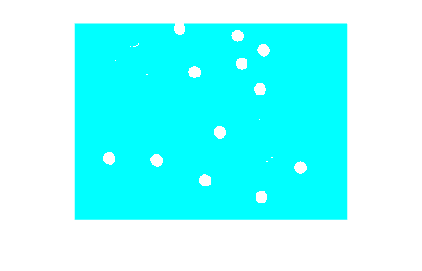

seg_otsu = imbinarize(korektur, thresh);
seg_otsu_rgb = label2rgb(seg_otsu);
imshow(seg_otsu_rgb, []);

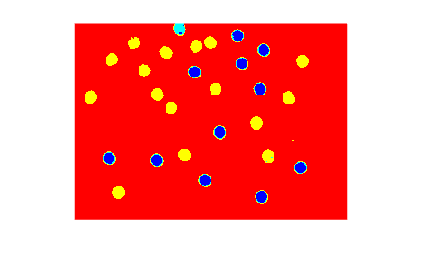

seg_multi = imquantize(korektur, threshs);
seg_multi_rgb = label2rgb(seg_multi);
figure;
imshow(seg_multi_rgb, []);

% g)
% Das Eregebnis deckt sich nicht mit meiner beobachtung, da eine Kugel als
% einzelne Objektart erkannt wird dadurch das sie etwas heller ist als die
% anderen dunklen Kugeln. Um dies zu korrigieren habe ich einen Filter von
% minimal 500 pixeln verwendet um die Anzahl zu bestimmen. Zudem muss noch
% 1 abgezogen werden um den Hintergrund zu berücksichtigen.

object_stats = regionprops(seg_multi, 'Area');
objects_counted = sum([object_stats.Area] > 500) -1;
disp(['Anzahl der verschiedenen Objekte: ', num2str(objects_counted)]);

Anzahl der verschiedenen Objekte: 2
